a = [1 -3; 1 -1; 1 1; 1 3];
y = [8 23 28 34]';


r = inv(a.' * a) * (a.' *y)

r =    23.2500
    4.1500


% or, r can also be defined this way: r = mldivide(a.'*a, a.'*y)

r =    23.2500
    4.1500


a_2 = [1 -3 9; 1 -1 1; 1 1 1; 1 3 9];
r_2 = inv(a_2.' *a_2) * (a_2.' * y);

a_3 = [1 -3 9 -27; 1 -1 1 -1; 1 1 1 1; 1 3 9 27];
r_3 = inv(a_3.' *a_3) * (a_3.' * y);

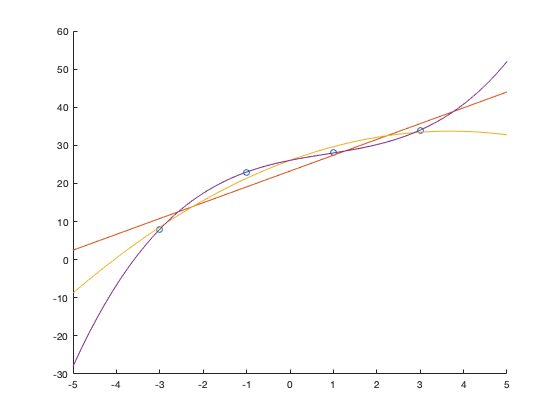

coded_humidity = [-3 -1 1 3];
electrical_conductivity = [8 23 28 34];
scatter(coded_humidity,electrical_conductivity);
hold on 

x = linspace(-5,5);
y = r(1,:) + r(2,:)*x;
plot(x, y)



y_2 = r_2(1,:) + r_2(2,:)*x + r_2(3,:)*x.^2;
plot(x,y_2)

y_3 = r_3(1,:) + r_3(2,:)*x + r_3(3,:)*x.^2 + r_3(4,:)*x.^3;
plot(x,y_3)